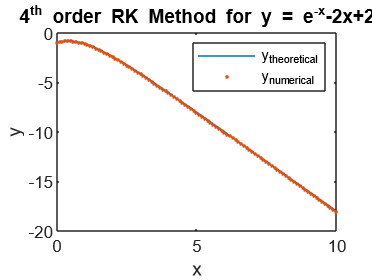

clc
clear
h = .1;  n = 100;

k1 = zeros(1,n); k2 = zeros(1,n); k3 = zeros(1,n); k4 = zeros(1,n);

yNumerical = zeros(1,n); yNumerical(1) = -1;
x(1) = 0; x = x(1):h:x(1)+h*n;

syms X Y;
myFunction = -2*X-Y;
yTheoretical = -3.*exp(-x)-2.*x+2;

for i=1:n
    k1(i) = h*subs(myFunction , [X,Y],[x(i) , yNumerical(i)]);
    k2(i) = h*subs(myFunction , [X,Y],[x(i)+h/2 , yNumerical(i)+k1(i)/2]);  
    k3(i) = h*subs(myFunction , [X,Y],[x(i)+h/2 , yNumerical(i)+k2(i)/2]);
    k4(i) = h*subs(myFunction , [X,Y],[x(i)+h , yNumerical(i)+k3(i)]);
    yNumerical(i+1) = yNumerical(i) + 1/6*(k1(i) + 2*k2(i) + 2*k3(i) + k4(i));
end

error = yTheoretical - yNumerical;
errorPercentage = error./yTheoretical;

plot(x,yTheoretical,x,yNumerical,'.')
title("4^{th} order RK Method for y = e^{-x}-2x+2")
xlabel("x"), ylabel("y")
legend("y_{theoretical}","y_{numerical}")